# Model Predictive Control - Exam Assignment 2021 - Prob 13

clear all; close all; clc;
addpath('Functions\')
addpath('Func2\')
% systemIdentification for finding the tfs

## Initialization

Gamma1 = 0.6; Gamma2 = 0.75; % Minimum Phase System
% Gamma1 = 0.45; Gamma2 = 0.4; % Non-Minimum Phase System

[p,a,A,g,rho] = get_parameters(Gamma1,Gamma2); 
[t0,t_f,Ts,t,T_plot,Nsim,F1,F2,F3,F4,x0,u,d,u_rep,d_rep] = get_simulationScenario();

u1 = 1.10*u_rep;  u2 = 1.25*u_rep;   u3 = 1.50*u_rep;   

% Steady states
xs0 = 5000*ones(4,1);       % Initial guess of steady state
us  = u;
xs  = fsolve(@ModifiedFourTankSystemWrap, xs0, [], u ,d , p); % Steady State


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ys  = FourTankSystemSensor(xs,p); % Get outputs
zs  = FourTankSystemOutput(xs,p); % Get measured outputs

% x0 = xs;

[Ac,Bc,Cc,Cz,Ec] = get_linearizedModel(p,xs);

% % For the SDE system
% Gc = diag([2^2 2^2 2^2 2^2]);
% [Acnew,Bcnew,Qcnew] = c2dzohsw(Ac,Bc,Gc,Ts) % Note that this is discrete time??

[Ad,Bd]=c2dzoh(Ac,Bc,Ts);
[~,Ed]=c2dzoh(Ac,Ec,Ts);
Cd = Cc;
Cdz = Cz;

[Qe,Rv,W,V,Qe_bar,W_bar,Gd_bar] = get_noise(Nsim,Ed);

% u_rep = u1;

# Transfer Functions

sys_d = ss(Ad,Bd,Cd,0,Ts)

sys_d =
 
  A = 
           x1      x2      x3      x4
   x1  0.9409       0  0.1814       0
   x2       0  0.9559       0  0.1188
   x3       0       0  0.8128       0
   x4       0       0       0  0.8785
 
  B = 
            u1       u2
   x1    2.328  0.09487
   x2  0.09782    2.933
   x3        0   0.9032
   x4    1.501        0
 
  C = 
             x1        x2        x3        x4
   y1  0.002631         0         0         0
   y2         0  0.002631         0         0
   y3         0         0  0.002631         0
   y4         0         0         0  0.002631
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Sample time: 4 seconds
Discrete-time state-space model.



Gd = tf(sys_d)

Gd =
 
  From input 1 to output...
        0.006125
   1:  ----------
       z - 0.9409
 
       0.0002573 z + 0.0002428
   2:  -----------------------
       z^2 - 1.834 z + 0.8398
 
   3:  0
 
        0.003948
   4:  ----------
       z - 0.8785
 
  From input 2 to output...
       0.0002496 z + 0.0002282
   1:  -----------------------
       z^2 - 1.754 z + 0.7647
 
        0.007717
   2:  ----------
       z - 0.9559
 
        0.002376
   3:  ----------
       z - 0.8128
 
   4:  0
 
Sample time: 4 seconds
Discrete-time transfer function.



Ts = 4;
Nmax = 300;
tol = 1.0e-8;
Dd = zeros(2,2)

Dd =      0     0
     0     0


% H = mimodss2dimpulse(Ad,Bd,Cz,Dd,Nmax)
% S = mimodss2dstep(Ad,Bd,Cz,Dd,N);        % Step response of approximate state space model
% p = 2;          % number of outputs
% m = 2;          % number of inputs 
% figure(1)                                 % Plot the results (blue = exact, red = approx.)
% sgtitle('Normalized Discreteized Transfer Functions')
%   s1= zeros(N+1,1);
% for i=1:m
%     for j=1:p
%         for k=1:N+1
%       
%             s1(k) = S(j,i,k);
%        
%         end
%         j
%         subplot(p,m,(j-1)*m+i)
% %         hold on;
%         plot(s1,'r-');grid on;
%         xlabel('Time [s]')
%         ylabel('Amplitude')
%         title("D_{" + j + i + "}(z)")
% %         hold off
%     end
% 
% end

# P, PI and PID Controllers

%%%%%%%   P
[C_p_1,info] = pidtune(Gd(1,1),'P') % 

C_p_1 =
 
  Kp = 171
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.2852
           PhaseMargin: 59.9880


[C_p_2,info] = pidtune(Gd(1,2),'P')

C_p_2 =
 
  Kp = 103
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0473
           PhaseMargin: 60.0045


[C_p_3,info] = pidtune(Gd(2,1),'P')

C_p_3 =
 
  Kp = 46.7
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0327
           PhaseMargin: 60.0068


[C_p_4,info] = pidtune(Gd(2,2),'P')

C_p_4 =
 
  Kp = 135
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.2797
           PhaseMargin: 59.9975




T_p_1 = feedback(C_p_1*Gd(1,1), 1);
T_p_2 = feedback(C_p_2*Gd(1,2), 1);
T_p_3 = feedback(C_p_3*Gd(2,1), 1);
T_p_4 = feedback(C_p_4*Gd(2,2), 1);

% figure(2)
% sgtitle('P-Controllers')
% subplot(2,2,1)
% title('u_1 to y_1')
% step(T_p_1);grid on;
% subplot(2,2,2)
% title('u_2 to y_1')
% step(T_p_2);grid on;
% subplot(2,2,3)
% title('u_1 to y_2')
% step(T_p_3);grid on;
% subplot(2,2,4)
% title('u_2 to y_2')
% step(T_p_4);grid on;

% u1y1_p = step(T_p_1);
% u2y1_p = step(T_p_2);
% u1y2_p = step(T_p_3);
% u2y2_p = step(T_p_4);

% figure(2)
% sgtitle('P-Controllers')
% subplot(2,2,1)
% title('u_1 to y_1')
% step(T_p_1);grid on;
% subplot(2,2,2)
% title('u_2 to y_1')
% step(T_p_2);grid on;
% subplot(2,2,3)
% title('u_1 to y_2')
% step(T_p_3);grid on;
% subplot(2,2,4)
% title('u_2 to y_2')
% step(T_p_4);grid on;



%%%% PI

[C_pi_1,info] = pidtune(Gd(1,1),'PI')

C_pi_1 =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 13.1, Ki = 0.491, Ts = 4
 
Sample time: 4 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0291
           PhaseMargin: 60.0000


[C_pi_2,info] = pidtune(Gd(1,2),'PI')

C_pi_2 =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 44.2, Ki = 0.676, Ts = 4
 
Sample time: 4 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0255
           PhaseMargin: 60.0000


[C_pi_3,info] = pidtune(Gd(2,1),'PI')

C_pi_3 =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 19.1, Ki = 0.21, Ts = 4
 
Sample time: 4 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0173
           PhaseMargin: 60.0000


[C_pi_4,info] = pidtune(Gd(2,2),'PI')

C_pi_4 =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 6.89, Ki = 0.2, Ts = 4
 
Sample time: 4 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0204
           PhaseMargin: 60.0000




T_pi_1 = feedback(C_pi_1*Gd(1,1), 1);
T_pi_2 = feedback(C_pi_2*Gd(1,2), 1);
T_pi_3 = feedback(C_pi_3*Gd(2,1), 1);
T_pi_4 = feedback(C_pi_4*Gd(2,2), 1);

% figure(3)
% sgtitle('PI-Controllers')
% subplot(2,2,1)
% step(T_pi_1);grid on;
% subplot(2,2,2)
% step(T_pi_2);grid on;
% subplot(2,2,3)
% step(T_pi_3);grid on;
% subplot(2,2,4)
% step(T_pi_4);grid on;


%%%% PID

[C_pid_1,info] = pidtune(Gd(1,1),'PID')

C_pid_1 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 16.7, Ki = 0.417, Kd = 31.8, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0291
           PhaseMargin: 74.0947


[C_pid_2,info] = pidtune(Gd(1,2),'PID')

C_pid_2 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 50.6, Ki = 0.831, Kd = 681, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0255
           PhaseMargin: 74.1523


[C_pid_3,info] = pidtune(Gd(2,1),'PID')

C_pid_3 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 21.9, Ki = 0.259, Kd = 449, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0173
           PhaseMargin: 74.1798


[C_pid_4,info] = pidtune(Gd(2,2),'PID')

C_pid_4 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 9, Ki = 0.17, Kd = 17.3, Ts = 4
 
Sample time: 4 seconds
Discrete-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0204
           PhaseMargin: 73.7753




T_pid_1 = feedback(C_pid_1*Gd(1,1), 1);
T_pid_2 = feedback(C_pid_2*Gd(1,2), 1);
T_pid_3 = feedback(C_pid_3*Gd(2,1), 1);
T_pid_4 = feedback(C_pid_4*Gd(2,2), 1);

% figure(4)
% sgtitle('PID-Controllers')
% subplot(2,2,1)
% step(T_pid_1);grid on;
% subplot(2,2,2)
% step(T_pid_2);grid on;
% subplot(2,2,3)
% step(T_pid_3);grid on;
% subplot(2,2,4)
% step(T_pid_4);grid on;

TT = (0:Ts:400);

u1y1_p = step(T_p_1,TT);
u2y1_p = step(T_p_2,TT);
u1y2_p = step(T_p_3,TT);
u2y2_p = step(T_p_4,TT);

u1y1_pi = step(T_pi_1,TT);
u2y1_pi = step(T_pi_2,TT);
u1y2_pi = step(T_pi_3,TT);
u2y2_pi = step(T_pi_4,TT);

u1y1_pid = step(T_pid_1,TT);
u2y1_pid = step(T_pid_2,TT);
u1y2_pid = step(T_pid_3,TT);
u2y2_pid = step(T_pid_4,TT);

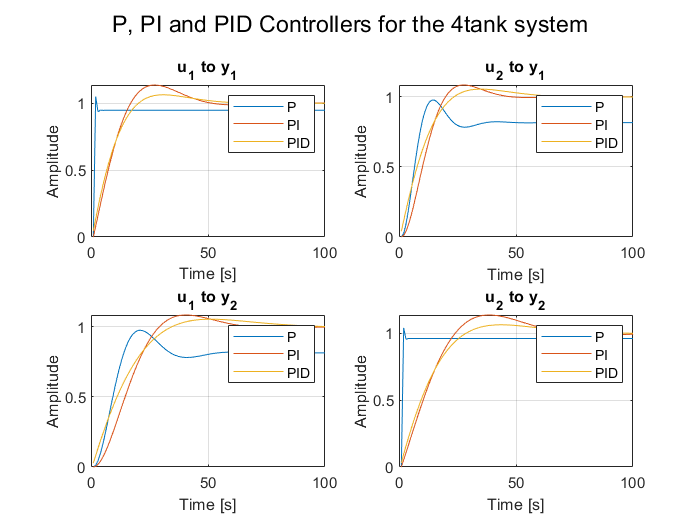

figure;
sgtitle('P, PI and PID Controllers for the 4tank system')

subplot(2,2,1)
plot(u1y1_p); hold on;
plot(u1y1_pi); hold on;
plot(u1y1_pid); hold off;
title('u_1 to y_1');
xlim([0 100]); grid on;
xlabel('Time [s]'); ylabel('Amplitude');
legend('P','PI','PID')

subplot(2,2,2)
plot(u2y1_p); hold on;
plot(u2y1_pi); hold on;
plot(u2y1_pid); hold off;
title('u_2 to y_1');
xlim([0 100]); grid on;
xlabel('Time [s]'); ylabel('Amplitude');
legend('P','PI','PID')

subplot(2,2,3)
plot(u1y2_p); hold on;
plot(u1y2_pi); hold on;
plot(u1y2_pid); hold off;
title('u_1 to y_2');
xlim([0 100]); grid on;
xlabel('Time [s]'); ylabel('Amplitude');
legend('P','PI','PID')

subplot(2,2,4)
plot(u2y2_p); hold on;
plot(u2y2_pi); hold on;
plot(u2y2_pid); hold off;
title('u_2 to y_2');
xlim([0 100]); grid on;
xlabel('Time [s]'); ylabel('Amplitude');
legend('P','PI','PID')